clear 
syms x f
f(x) = exp(x)

$$f(x) = {\mathrm{e}}^{x}$$

R11 = mypade(f, 1, 1, x);
simplifyFraction(R11)

$$ans = -\frac{x+2}{x-2}$$

pade(exp(x), x, 'Order', [sym(1), sym(1)])

$$ans = -\frac{x+2}{x-2}$$

R22 = mypade(f, 2, 2, x);
simplifyFraction(R22)

$$ans = \frac{x^{2}+6\,x+12}{x^{2}-6\,x+12}$$

pade(exp(x), x, 'Order', [sym(2), sym(2)])

$$ans = \frac{x^{2}+6\,x+12}{x^{2}-6\,x+12}$$

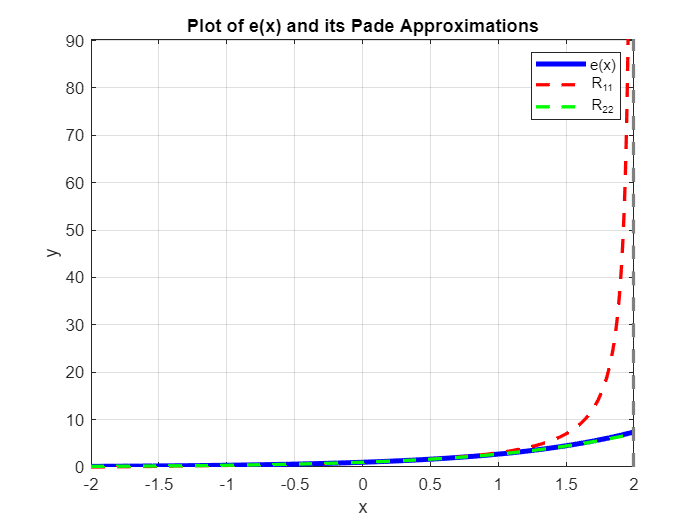

% Define the range of x values for plotting
k = 2;
y_values = [-k, k];
x_values = linspace(-k, k, 1000);

% Plot the functions
figure;
fplot(f, [-k, k], 'b', 'LineWidth', 3); % Plot e(x) in blue
hold on;
fplot(R11, [-k, k], 'r--', 'LineWidth', 2); % Plot R11 in red dashed line
fplot(R22, [-k, k], 'g--', 'LineWidth', 2); % Plot R22 in green dashed line
xlabel('x');
ylabel('y');
title('Plot of e(x) and its Pade Approximations');
legend('e(x)', 'R_{11}', 'R_{22}');
grid on;
hold off;

clear 
syms x f
f(x) = log(1+x);
R22 = mypade(f, 2, 2, x);
simplifyFraction(R22)

$$ans = \frac{3\,\left(x^{2}+2\,x\right)}{x^{2}+6\,x+6}$$

pade(f, x, 'Order', [sym(2), sym(2)])

$$ans(x) = \frac{3\,x\,\left(x+2\right)}{x^{2}+6\,x+6}$$

R31 = mypade(f, 3, 1, x);
simplifyFraction(R31)

$$ans = \frac{-x^{3}+6\,x^{2}+24\,x}{6\,\left(3\,x+4\right)}$$

pade(f, x, 'Order', [sym(3), sym(1)])

$$ans(x) = \frac{x\,\left(-x^{2}+6\,x+24\right)}{6\,\left(3\,x+4\right)}$$

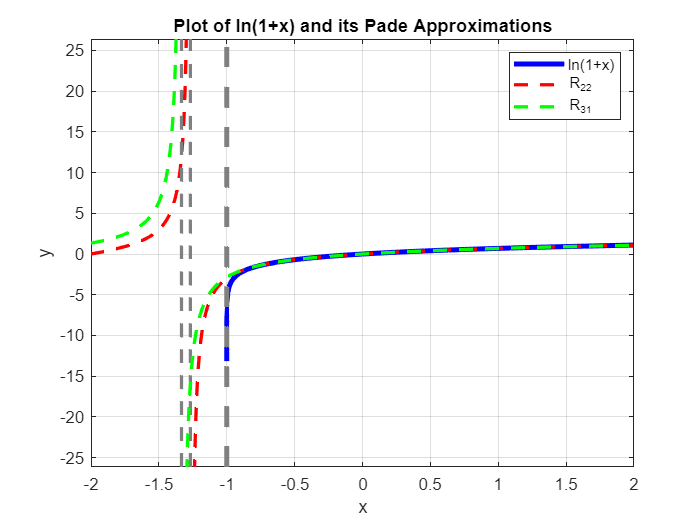

% Define the range of x values for plotting
k = 2;
y_values = [-k, k];
x_values = linspace(-k, k, 1000);

% Plot the functions
figure;
fplot(f, [-k, k], 'b', 'LineWidth', 3); % Plot e(x) in blue
hold on;
fplot(R22, [-k, k], 'r--', 'LineWidth', 2); % Plot R22 in red dashed line
fplot(R31, [-k, k], 'g--', 'LineWidth', 2); % Plot R31 in green dashed line
xlabel('x');
ylabel('y');
title('Plot of ln(1+x) and its Pade Approximations');
legend('ln(1+x)', 'R_{22}', 'R_{31}');
grid on;
hold off;